clear 
close all
scene = uavScenario(UpdateRate=2);
Map = 2;



%MAP3
%----------------------------------------------------------------
if Map == 3
    Data = matfile("3D\RLVFH\MapFinal_3.mat"');
    waypointsData = Data.FinalRoute
    waypoints = waypointsData;
    x = waypointsData(:,2);
    y = waypointsData(:,1);
    waypoints(:,1) = x;
    waypoints(:,2) = y;
    waypoints(:,3) = waypoints(:,3)*-1
    addMesh(scene,"polygon",{[11 9;13 9;13 10;11 10],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[31 4;33 4;33 15;31 15],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[19 24;31 24;31 25;19 25],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[43 20;44 20;44 26;43 26],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[31 27;46 27;46 40;31 40],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[26 36;29 36;29 37;26 37],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[5 28;16 28;16 38;5 38],[0 5]},0.651*ones(1,3))
    %addMesh(scene,"polygon",{[0 0;50 0;50 50;0 50],[0 2]},0.651*ones(1,3))
    uavPose = [6 12 -3 pi/2 0 0]';
    goalPose = [35 27 -3]';
    % wf = uavWaypointFollower(UAVType="multirotor", ...
    %                      TransitionRadius=1, ...
    %                      Waypoints=[6 12 -3; 35 27 -3]);
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=waypoints);

%MAP2
%------------------------------------------------------------------------
elseif Map == 2
    Data = matfile("3D\RLVFH\MapFinal_2.mat"');
    waypointsData = Data.FinalRoute
    waypoints = waypointsData;
    x = waypointsData(:,2);
    y = waypointsData(:,1);
    waypoints(:,1) = x;
    waypoints(:,2) = y;
    waypoints(:,3) = waypoints(:,3)*-1
    addMesh(scene,"polygon",{[8 10;20 10;20 25;8 25],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[26 18;29 18;29 31;26 31],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[33 21;37 21;37 34;33 34],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[39 13;42 13;42 26;39 26],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[1 27;16 27;16 40;1 40],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[14 42;25 42;25 44;14 44],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[27 40;39 40;39 50;27 50],[0 5]},0.651*ones(1,3))
    uavPose = [10 35 -5 pi/2 0 0]';
    goalPose = [45 5 -2]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=waypoints);

%MAP1
%--------------------------------------------------------------------------

elseif Map == 1
    Data = matfile("3D\RLVFH\MapFinal_1.mat"');
    waypointsData = Data.FinalRoute
    waypoints = waypointsData;
    x = waypointsData(:,2);
    y = waypointsData(:,1);
    waypoints(:,1) = x;
    waypoints(:,2) = y;
    waypoints(:,3) = waypoints(:,3)*-1
    addMesh(scene,"polygon",{[12 3;19 3;19 18;12 18],[0 4]},0.651*ones(1,3))  
    addMesh(scene,"polygon",{[30 10;42 10;42 15;30 15],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[38 17;50 17;50 24;38 24],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[5 23;7 23;7 24;5 24],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[16 27;24 27;24 36;16 36],[0 2]},0.651*ones(1,3))

    addMesh(scene,"polygon",{[31 31;46 31;46 39;31 39],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[5 37;18 37;18 42;5 42],[0 5]},0.651*ones(1,3))
    uavPose = [27 47 -2 pi/2 0 0]';
    goalPose = [5 10 -2]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=waypoints);

else
%MAP 4
%-------------------------------------------------------------------------
    Data = matfile("3D\RLVFH\MapFinal_4.mat"');
    waypointsData = Data.FinalRoute
    waypoints = waypointsData;
    x = waypointsData(:,2);
    y = waypointsData(:,1);
    waypoints(:,1) = x;
    waypoints(:,2) = y;
    waypoints(:,3) = waypoints(:,3)*-1
    addMesh(scene,"polygon",{[8 28;17 28;17 29;8 29],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[22 18;25 18;25 25;22 25],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[30 21;31 21;31 29;30 29],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[31 21;33 21;33 28;31 28],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[19 31;28 31;28 34;19 34],[0 2]},0.651*ones(1,3))

    addMesh(scene,"polygon",{[20 38;30 38;30 49;20 49],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[41 17;44 17;44 24;41 24],[0 4]},0.651*ones(1,3))
    uavPose = [35 3 -3 pi/2 0 0]';
    goalPose = [10 35 -5]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=waypoints);
end

waypointsData =     35    11     5
    34    12     5
    33    13     4
    32    14     3
    31    15     3
    31    16     4
    30    17     3
    29    18     3
    28    19     3
    27    20     3


waypoints =     11    35    -5
    12    34    -5
    13    33    -4
    14    32    -3
    15    31    -3
    16    31    -4
    17    30    -3
    18    29    -3
    19    28    -3
    20    27    -3


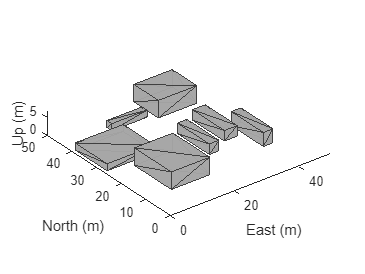


show3D(scene);
xlim([0 50])
ylim([0 50])
zlim([0 7])

model = multirotor;



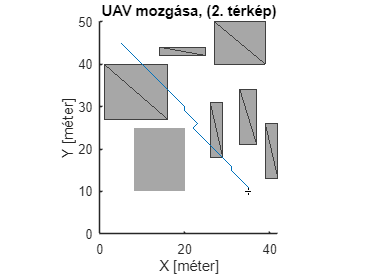





plat = uavPlatform("UAV",scene, ...
                   ReferenceFrame="NED", ...
                   InitialPosition=uavPose(1:3)', ...
                   InitialOrientation=eul2quat(uavPose(4:6)'));


updateMesh(plat,"quadrotor",{1.5},[0 0 0],eul2tform([0 0 pi]))
lidarmodel = uavLidarPointCloudGenerator(AzimuthResolution=0.3324099, ...
                                         ElevationLimits=[-10 30], ...
                                         AzimuthLimits=[-60 60], ...
                                         ElevationResolution=0.5, ...
                                         MaxRange=10, ...
                                         UpdateRate=2, ...
                                         HasOrganizedOutput=true);

lidar = uavSensor("Lidar",plat,lidarmodel, ...
                  MountingLocation=[0 0 -0.4], ...
                  MountingAngles=[0 0 180]);

figure(1)
[ax,plotFrames] = show3D(scene);
ax.Children(end).LineStyle = "none";



title("UAV mozgása, (" + Map +". térkép)")
xlim([0 50])
ylim([0 50])
zlim([0 7])
view(ax,2)
xlabel(ax, "X [méter]")
ylabel(ax, "Y [méter]")
zlabel(ax, "Z [méter]")
axis(ax,"equal")
hold(ax,"on")
plot3(waypointsData(:,1), waypointsData(:,2), waypointsData(:,3), Parent=ax)


vfh3D = controllerVFH3D(HistogramResolution=5, ...
                        MaxAge=0, ...
                        HorizontalSensorFOV=lidarmodel.AzimuthLimits, ...
                        VerticalSensorFOV=lidarmodel.ElevationLimits, ...
                        SensorLocation=lidar.MountingLocation, ...
                        SensorOrientation=lidar.MountingAngles([3 2 1]));

% Specify lookahead distance for the desired point along obstacle-free
% direction, and for the waypoint follower. 
lookaheadOA = 2;
lookaheadWF = 6;

% Set up UAV initial state. The UAV state space is position, linear velocity,
% attitude Euler angles, angular velocity, thrust and integral error.
uavPosition = uavPose(1:3);
uavOrientation = eul2quat(uavPose(4:6)')';
intErr = [0;0;0];
initialState = [uavPosition(1); uavPosition(2); uavPosition(3); ...
                0; 0; 0; uavPose(4); 0; 0; 0; 0; 0; 0; intErr];

% Set the PID controller parameters.
kp = 15;
kd = 12;
ki = 0.005;
kyaw = 10;

% Set up simulation start time and integration interval.
tStart = 0;
tStep = 0.1;

% Solution time points.
hStep = tStep/10;

% Number of iterations.
numIter = 400;

% Store time and states.
tTotal = zeros(numIter*(tStep/hStep+1),1);

% Number of states is equal to the number of model states plus
% integral error.
numStates = numel(model.state)+3;
states = zeros(numIter*(tStep/hStep+1),numStates);

vfh3D.DistanceLimits = [0.1 2];

vfh3D.TargetDirectionWeight = 5;
vfh3D.PreviousDirectionWeight = 2;
vfh3D.CurrentDirectionWeight = 2;

vfh3D.VehicleRadius = 0.5;     
vfh3D.SafetyDistance = 0.5;  


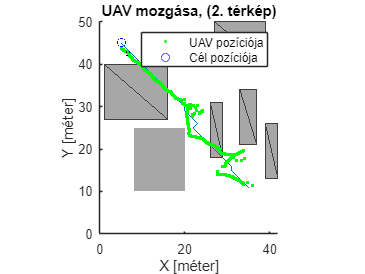

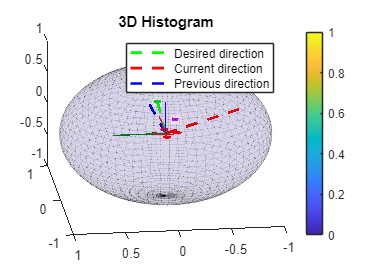

Reached = logical
   1


setup(scene)
Reached = false;
idx = 1;
while ~Reached
% Simulate 
%for idx = 1:numIter
    
    [isupdated,lidarSampleTime,pt] = read(lidar);
    xLidar = reshape(pt.Location(:,:,1),[],1);
    yLidar = reshape(pt.Location(:,:,2),[],1);
    zLidar = reshape(pt.Location(:,:,3),[],1);

    sensorPoints = [xLidar yLidar zLidar];
  
    [targetPosition,~,desYaw] = wf(uavPose(1:4),lookaheadWF);

    [desiredDirection,desiredYaw,status] = vfh3D(uavPosition,uavOrientation, ...
                                                 sensorPoints,targetPosition);

    % Visualize the histogram.
    figure(2)
    show(vfh3D);


    % Select desired position along the obtacle-free direction.
    desiredPosition = uavPosition + lookaheadOA*desiredDirection;

    [t,y] = ode23(@(t,x)exampleHelperDerivative(t,x,model,desiredPosition,desiredYaw,kp,kd,ki,kyaw), ...
                  tStart:hStep:tStart + tStep,initialState);

    % Store data.
    tTotal((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1)) = t;
    states((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1),:) = y;

    % Update states.
    uavPosition = y(end,1:3)';
    uavOrientEul = y(end,7:9)';
    uavOrientation = eul2quat(uavOrientEul')';
    tStart = t(end);
    initialState = y(end,:);
  
    % Plot the path.
    desPosition = plot3(desiredPosition(2),desiredPosition(1),-desiredPosition(3),".g",Parent=ax);
    %tgtPosition = plot3(targetPosition(2),targetPosition(1),-targetPosition(3),".r",Parent=ax);
    goalPosition = plot3(wf.Waypoints(end,2),wf.Waypoints(end,1),-wf.Waypoints(end,3),"ob",Parent=ax);
    legend(ax,[desPosition goalPosition],["UAV pozíciója","Cél pozíciója"])
   
    if isupdated
        % Use fast update to move platform visualization frames.
        show3D(scene,Parent=ax,Time=lidarSampleTime,FastUpdate=true);
        % Move the platform.
        move(plat,[uavPosition' y(end,4:6) zeros(1,3) eul2quat(uavOrientEul') zeros(1,3)]);
        drawnow limitrate
    end

    % Advance scene simulation time.
    advance(scene);

    % Update all sensors in the scene.
    updateSensors(scene)

    uavPose = [uavPosition; quat2eul(uavOrientation',"ZYX")'];
    ReachedCoordinates = abs(uavPose(1:3)-goalPose);
    if ReachedCoordinates(1) < 2.5 && ReachedCoordinates(2) < 2.5 && ReachedCoordinates(3) < 2.5
        Reached = true
    end
    idx = idx+1;
end

figure(3)
idx

idx = 265

(idx-1)*(tStep/hStep+1)

ans = 2904

hStep

hStep = 0.0100

states((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1),:)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


states

states =    10.0000   35.0000   -5.0000         0         0         0    1.5708         0         0         0         0         0         0         0         0         0
   10.0000   35.0000   -5.0010    0.0058    0.0052   -0.1958    1.4797   -0.0521   -0.0495   -8.4468   -8.1282   -9.5410    2.8795    0.0142    0.0091   -0.0107
   10.0002   35.0002   -5.0038    0.0344    0.0281   -0.3694    1.3928   -0.1474   -0.1364   -9.9999   -8.5100   -9.4149    2.6137    0.0285    0.0181   -0.0215
   10.0008   35.0006   -5.0083    0.0879    0.0645   -0.5129    1.3142   -0.2374   -0.2183   -9.1881   -6.3201   -8.8518    2.3959    0.0427    0.0272   -0.0322
   10.0020   35.0015   -5.0140    0.1603    0.1056   -0.6295    1.2429   -0.3074   -0.2837   -7.7108   -3.8524   -7.8544    2.2181    0.0569    0.0362   -0.0428
   10.0040   35.0027   -5.0208    0.2446    0.1449   -0.7239    1.1784   -0.3564   -0.3322   -6.2210   -1.8842   -6.7353    2.0658    0.0711    0.0453   -0.0534
   10.0069   35.0044   -5

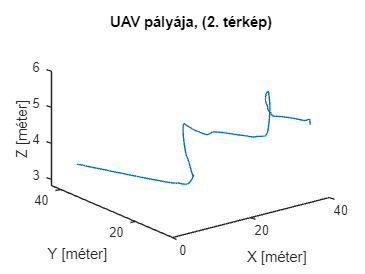

plot3(states(1:(idx-1)*(tStep/hStep+1),2),states(1:(idx-1)*(tStep/hStep+1),1),-states(1:(idx-1)*(tStep/hStep+1),3))
title("UAV pályája, (" + Map +". térkép)")
xlabel("X [méter]")
ylabel("Y [méter]")
zlabel("Z [méter]")


DataMatrix = [states(1:(idx-1)*(tStep/hStep+1),1) states(1:(idx-1)*(tStep/hStep+1),2) -states(1:(idx-1)*(tStep/hStep+1),3)]

DataMatrix =    10.0000   35.0000    5.0000
   10.0000   35.0000    5.0010
   10.0002   35.0002    5.0038
   10.0008   35.0006    5.0083
   10.0020   35.0015    5.0140
   10.0040   35.0027    5.0208
   10.0069   35.0044    5.0284
   10.0107   35.0063    5.0367
   10.0154   35.0085    5.0456
   10.0210   35.0109    5.0549


save("3D\RLVFH\VFHRLMatrix" + Map +".mat", "DataMatrix")